## Multivariable Taylor Approximations:

Now we can make functions to approximate data. There is all sorts of analysis that could be run from here. One issue that may arise however is that the function is difficult to compute. This will affect any process where you have to evaluate the function repeatedly e.g. optimization. In these situations, it may be helpful to approximate the function at certain points. 

Similar to single variable functions, multivariable functions can be approximated at distinct points with Taylor polynomials. Let's say we want to make a function $g\left(x,y\right)$ that is an approximation of the function $f\left(x,y\right)$ at the point $\left(a,b\right)$. A 0th order approximation would be defined as:


$$g\left(x,y\right)=f\left(a,b\right)$$


This approximation is accurate at the point $\left(a,b\right)$, but not so much anywhere else. The approximation can be improved by making $g\left(x,y\right)$ have the same derivative as $f\left(x,y\right)$ at the point $\left(a\ldotp b\right)$. With a multivariable function, this would be defined as:


$$g\left(x,y\right)=f\left(a,b\right)+\left(\frac{\partial }{\partial x}f\left(a,b\right)\left(x-a\right)+\frac{\partial }{\partial y}f\left(a,b\right)\left(y-b\right)\right)$$


This can be represented much simpler using vector notation and the gradient:


$$g\left(v\right)=f\left(\alpha \right)+\nabla f\left(\alpha \right)\cdot \left(v-\alpha \right)$$



$$v=\left(x,y\right)$$
     


$$\alpha =\left(a,b\right)$$


Note the use of a dot product between the gradient of $f$ and the difference term $\left(v-\alpha \right)$. In this definition $v$ and $\alpha$ aren't limited to just two terms. The formula works for scalar valued functions with any number of inputs. Visually the second order Taylor approximation of a multivariable function forms a tangent plane as such:

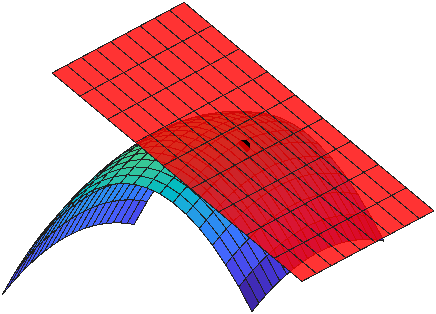

Taylor approximations get a little more difficult with multivariable functions after the first degree. This is because higher degree derivatives of multivariable functions have increasingly more partial derivatives. It is still somewhat reasonable though to define the second order approximation:


$$g\left(x,y\right)=f\left(a,b\right)+\left(\frac{\partial }{\partial x}f\left(a,b\right)\left(x-a\right)+\frac{\partial }{\partial y}f\left(a,b\right)\left(y-b\right)\right)+\frac{1}{2}\left(\frac{\partial^2 }{\partial x^2 }f\left(a,b\right){\left(x-a\right)}^2 +\frac{\partial^2 }{\partial x\partial y}f\left(a,b\right)\left(x-a\right)\left(y-b\right)+\frac{\partial^2 }{\partial y\partial x}f\left(a,b\right)\left(y-b\right)\left(x-a\right)+\frac{\partial^2 }{\partial y^2 }f\left(a,b\right){\left(y-b\right)}^2 \right)$$


Employing the Hessian matrix, the above formula can be written in vector form as:


$$g\left(v\right)=f\left(\alpha \right)+\nabla f\left(\alpha \right)\cdot \left(v-\alpha \right)+\frac{1}{2}{\left(v-\alpha \right)}^T Hf\left(\alpha \right)\left(v-\alpha \right)\;$$


Visually the second order approximation looks like a paraboloid:

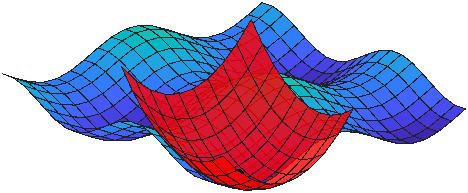

Using these approximations, many complex functions that would otherwise be impractical to work with can be efficiently calculated and analyzed.

#### Exercise: Find the first order Taylor polynomial of $\frac{14}{9}x^2 +y^2 +\frac{1}{9}\mathrm{xy}+\frac{1}{3}x$ at the point $\left(1,-1\right)$

% The checks expect a symbolic function in terms of x and y
% Make sure the solution is assigned 
syms x y
f = 14./9.*x.^2+y.^2+1./9.*x.*y+1./3.*x;
% Do not edit above this line

Approximation = % YOUR CODE HERE

% CHECKS (DO NOT EDIT)
assert(double(subs(Approximation,[x y],[1,-1]))==double(subs(f,[x y],[1,-1])),"Approximation does not match original function at the point (1,-1)")
assert(double(subs(Approximation,[x y],[1,2]))==-26./9,"Approximation does not match answer key at the point (1,2)")
assert(double(subs(Approximation,[x y],[-2,3]))==-133./9,"Approximation does not match answer key at the point (-2,3)")
assert(double(subs(Approximation,[x y],[0,1]))==-13./3,"Approximation does not match answer key at the point (0,1)")
disp("All Tests Passed")